# **Plotting in MATLAB**

This lecture will cover some of the plotting options in MATLAB. We will continue to use the Framingham dataset from the previous lecture. 

fram = readtable('frmgham2.xls');

For simplifying the following plotting exercises, we will just look at the first 100 patients in the dataset.

fram = head(fram,100);

# Plotting Datasets

There are many different ways to plot data in MATLAB and also several ways to generate these figures. Let's start by looking at the age data from our revised Framingham dataset.

age = fram.AGE;

Now that we have the age array saved as a variable, there are two ways to plot it:

    **Option 1: **Select the variable in the Workspace, go to Plots tab, and select the 2-D line plot. 

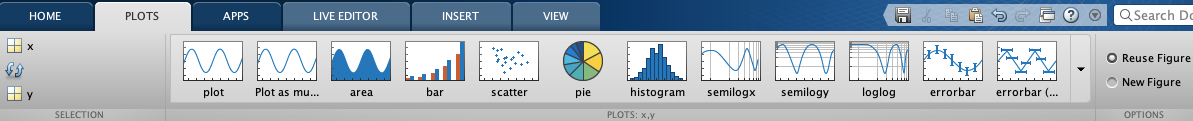

MATLAB will then create the plot for you in a new figure window and display the corresponding plotting command in the Command Window.

    **Option 2:** Use the *plot *command:

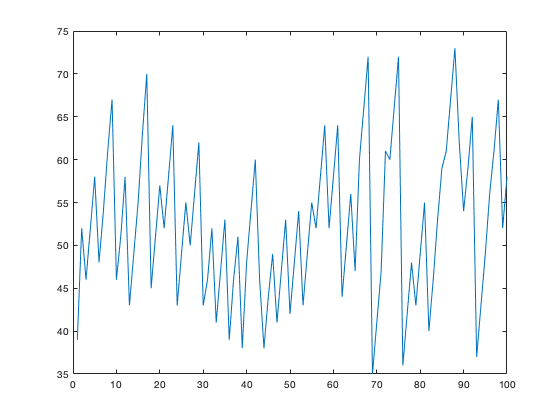

plot(age)

The figure includes the ages of all 100 patients, with age given on the y-axis and the index on the x-axis. Clearly we need to add some information to this plot and find a better way to display the data.

When viewing the plot in a figure window, we can use the Insert tab to add elements such as axis labels and titles. When you are done adding these features, there is an option to generate the code for these changes.

Once again, if you do not wish to use the tab tools, you can directly generate plots in your script with the appropriate commands. Let's add axis labels and a title to our plot, while also changing our plot style from a line graph to red circles .

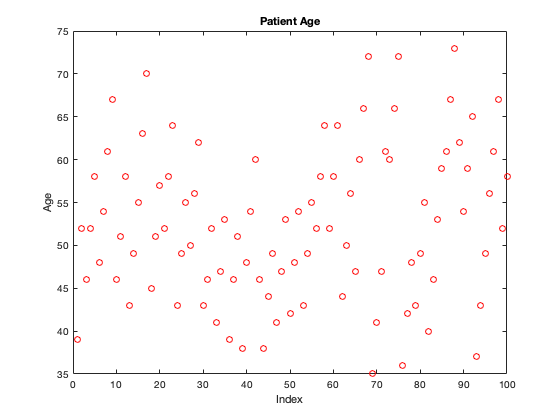

plot(age,'ro')
xlabel('Index')
ylabel('Age')
title('Patient Age')

### **Log-Log**

The log-log function simply generates a plot with a log scale on both axes. This may not necessarily be a useful tool for the variables in the Framingham dataset, but let's try it on the glucose data as an example. 

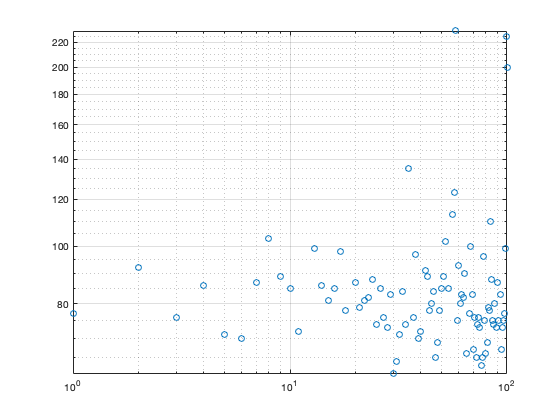

glucose = fram.GLUCOSE;
loglog(glucose,'o')
grid on

### **Bar Graphs**

Bar graphs are useful for comparing data from different groups. 

Create a bar graph that looks at education level versus average cigarettes smoked per day. First, we must create our bar graph categories and specify the order in which they will display:

sex = categorical({'male','female'});
sex = reordercats(sex,{'male','female'})

sex = 1×2 categorical array
     male      female 


Next, extract the cigarettes per day data for each gender and find the mean values. Note that we must convert from a table to an array in order to use the *mean *function.


male_cigs = table2array(fram(fram.SEX == 1,'CIGPDAY'));
female_cigs = table2array(fram(fram.SEX == 2,'CIGPDAY'));

mean_male_cigs = mean(male_cigs);
mean_female_cigs = mean(female_cigs);
mean_cigs = [mean_male_cigs,mean_female_cigs]

mean_cigs =    11.9388   10.5686


Finally, create the bar graph with the *bar *function. Let's make the bars blue and the bar width set to half of the available space.

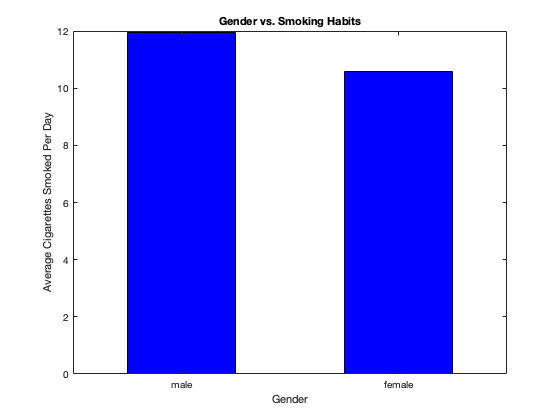

bar(sex,mean_cigs,0.5,'blue')
xlabel('Gender');
ylabel('Average Cigarettes Smoked Per Day');
title('Gender vs. Smoking Habits')

### **Pie Chart**

Pie charts are useful for looking at the composition of a group. 

Let's make a pie chart which shows the education levels (1 to 4) within the Framingham dataset. We first need to find the number of patients who received each level of education. We will use a for loop and the* nnz *function to do this:

education = (fram.educ);
i=1;
for i=1:4
    educ_pie(i)=nnz(education==i);
    i=i+1;
end
educ_pie

educ_pie =     34    33    18     9


It looks like the for loop worked, however we need to make sure that the sum of our array elements is equal to 100, as we want to make sure the entire patient group is represented in the pie chart

sum(educ_pie)

ans = 94

We know that the Framingham dataset contains some missing values. Confirm that this is the case with our education data.

nan = sum(isnan(education))

nan = 6

As expected, we are missing six data points, which would bring the total to 100. Add this data to the education array so that it is incorported into the pie chart.

educ_pie(5) = nan;
educ_pie

educ_pie =     34    33    18     9     6


We are finally ready to make the pie chart. 

labels = {'1', '2', '3', '4','No Data'}

labels = 1×5 cell array
    {'1'}    {'2'}    {'3'}    {'4'}    {'No Data'}


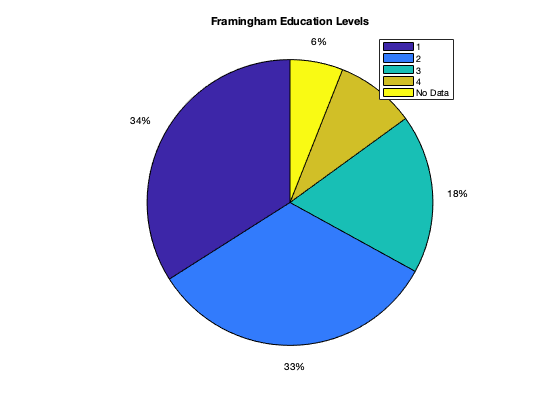

pie(educ_pie)
legend(labels)
title('Framingham Education Levels')

#### **Histograms**

Histograms are used to look at the distribution of continuous data. The dataset is displayed as a series of bins, which we can adjust to our preference.

Plot a histogram showing the heart rate distribution of the patient group.

heart_rate = fram.HEARTRTE;
h = histogram(heart_rate)

h =   Histogram with properties:

             Data: [100×1 double]
           Values: [3 19 36 23 13 4 2]
          NumBins: 7
         BinEdges: [50 60 70 80 90 100 110 120]
         BinWidth: 10
        BinLimits: [50 120]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


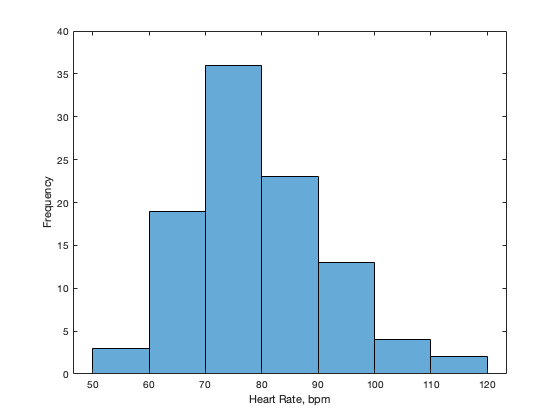

xlabel('Heart Rate, bpm')
ylabel('Frequency')

Now break down the data into 10 bins and change the bin color.

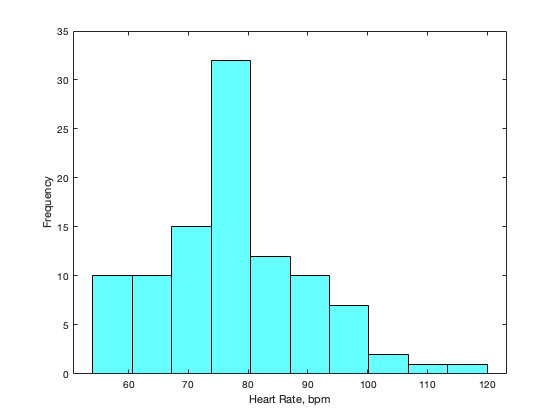

h =   Histogram with properties:

             Data: [100×1 double]
           Values: [10 10 15 32 12 10 7 2 1 1]
          NumBins: 10
         BinEdges: [54 60.6000 67.2000 73.8000 80.4000 87 93.6000 100.2000 106.8000 113.4000 120]
         BinWidth: 6.6000
        BinLimits: [54 120]
    Normalization: 'count'
        FaceColor: [0 1 1]
        EdgeColor: [0 0 0]

  Show all properties


h.NumBins = 10;
h.FaceColor = 'cyan'

### Boxplots

Boxplots are also helpful for looking at data distribution. In addition to showing the shape of the distribution, boxplots display the median value, the interquartile range, minimum/maxmimum values, and outlier points.

Examine total cholesterol versus sex using a boxplot.

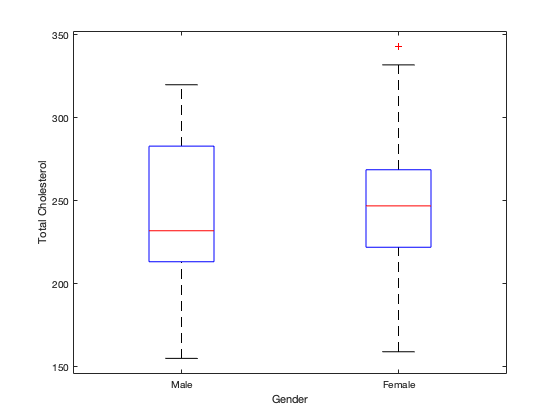

boxplot(fram.TOTCHOL,fram.SEX,'Labels',{'Male','Female'})
xlabel('Gender')
ylabel('Total Cholesterol')

### Correlation

MATLAB has many tools for examining the relationship between variables. Use the *lsline *command to plot the least squares regression line for systolic and diastolic blood pressure. 

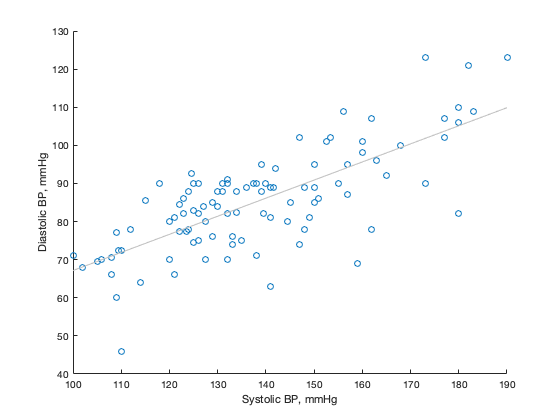

sys = fram.SYSBP;
dia = fram.DIABP;
scatter(sys,dia)
lsline
xlabel('Systolic BP, mmHg');
ylabel('Diastolic BP, mmHg');

Next, calculate the correlation coefficient between systolic and diastolic blood pressure. The correlation coefficient, *r, *indicates the strength and direction of the relationship between the two variables.

r = corr(sys,dia)

r = 0.7429

We can also create a linear fit model for between the two variables using the *fitlm* command:

lrm = fitlm(sys,dia)

lrm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)     19.679       6.0262    3.2656    0.0015057
    x1             0.47475     0.043212    10.986     8.88e-19


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 9.1
R-squared: 0.552,  Adjusted R-Squared: 0.547
F-statistic vs. constant model: 121, p-value = 8.88e-19

The output shows the model formula, the coefficients, and model summary. The coefficient of determination, r^2, is given in the model summary, but it can also be found with the below command:

r2 = lrm.Rsquared.Ordinary

r2 = 0.5519

The coefficient of determination measures the amount of variance of one variable that can be explained by the other. In our example, r^2 is equal to 0.506. This means that 50.6% of the variance in the diastolic blood pressure can be explained by the systolic blood pressure data. This can be used as an indicator for how good of a fit the least squares regression line is. 

# Further Practice

### Histogram: Age vs Frequency

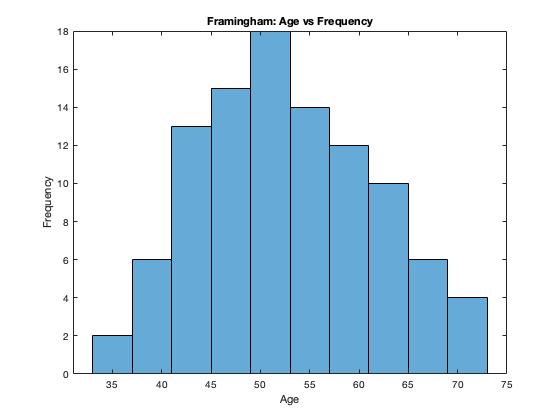

age = fram.AGE;
histogram(age,10)

title('Framingham: Age vs Frequency')
xlabel('Age')
ylabel('Frequency')

### Boxplot: Education Level vs Heart rate

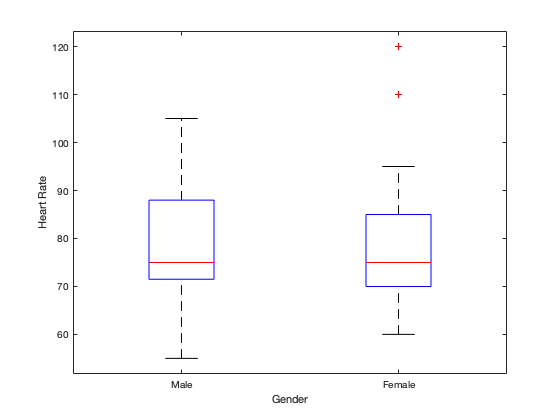

gender = fram.SEX;
boxplot(heart_rate, gender,'Labels',{'Male','Female'})
ylabel('Heart Rate')
xlabel('Gender')

### Education vs BMI

What is best way to show this relationship?

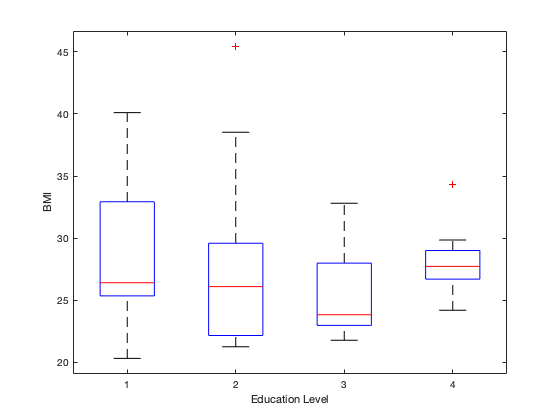

BMI = fram.BMI;
boxplot(BMI,education)
ylabel('BMI')
xlabel('Education Level')